# **ACTIVIDAD 2. Análisis de robot lineal de 3GDL**

Jesús Alejandro Gómez Bautista - A01736171

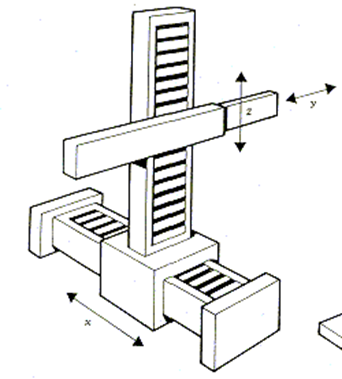

El siguiente live script contiene la solución a la actividad 2 y su correspondiente documentación de código, así como la explicación de los resultados obtenidos y de la implementación o codificación de ciertos elementos que permiten su funcionamiento conforme a lo visto durante clase. 

## **ETAPA 0. Definiendo el entorno de trabajo y sus variables.**

%Limpieza de pantalla
clear all
close all
clc

*Explicación:* Estas primeras líneas de código dentro del programa nos permiten limpiar el entorno de trabajo, cerrar las figuras preexistentes (en caso de existir) y limpiar la ventana de comandos para evitar sobrescrituras o errores en caso de existir elementos compartidos con otros códigos.

%Declaración de variables simbólicas
syms l1(t) l2(t) l3(t) t 

*Explicación: *Para realizar cálculos simbólicos diferenciales, es necesario emplear variables simbólicas que representan valores numéricos con los que aún no contamos. A diferencia del último tipo de robot trabajado, en esta ocasión no es necesario declarar los ángulos theta de la apertura, dado que este robot se desplaza de manera lineal y no angular, esto debido al modelo del robot, por lo que solo nos interesa la longitud del eje.

## **ETAPA I. Grados de libertad**

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[1 1 1];

%Creamos el vector de coordenadas articulares
Q= [l1, l2, l3];
disp('Coordenadas generalizadas');

Coordenadas generalizadas


pretty (Q);

(l1(t), l2(t), l3(t))



Explicación: La línea 7 define a un vector para representar el tipo de junta que el robot presenta, en este caso las juntas existentes en un robot lineal son de tipo prismática. Las líneas siguientes nos permiten crear el vector donde las coordenadas articulares se localizarán y nos permitirán desplegarlas en el entorno de trabajo.

%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
disp('Velocidades generalizadas');

Velocidades generalizadas


pretty (Qp);

/  d         d         d       \
| -- l1(t), -- l2(t), -- l3(t) |
\ dt        dt        dt       /




%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

Explicación: Las primeras 3 líneas de esta sección se encargan de calcular de manera diferencial el vector Q con respecto al tiempo, resultando así nuestro vector de velocidades articulares generalizadas expresado de manera más sencilla mediante pretty. A continuación, a través de la función size en la variable GDL (Grados De Libertad), calculamos el número de grados de libertad del robot, el cual es igual al número de columnas del vector RP, en este caso, trabajaremos con un robot con 3 grados de libertad. La línea debajo hace la conversión de este valor numérico a uno tipo string.

**Articulación 1**

%Posición de la articulación 1 respecto a 0
P(:,:,1)= [0 ; 0; l1];
%Matriz de rotación de la junta 1 respecto a 0.... -90º y1 
R(:,:,1)= [0  0 -1 ;
           0  1  0;
           1  0  0];

Explicación: La matriz P representa la posición de la articulación uno con respecto a la base, en este caso, se define a la articulación 1 en la ubicación (0, 0, L1) donde este último es igual a la longitud de la junta prismática. En cuanto a la matriz R, representa la rotación con respecto a la base, donde el eje x de la articulación está alineado con el eje z de la base (rotación de -90 en el eje y), y de la articulación con el y de la base y el eje z de la articulación con el eje x de la base (rotación de -90 alrededor de y).

**Articulación 2**

%Posición de la articulación 2 respecto a 1
P(:,:,2)= [0; l3 ; 0];
%Matriz de rotación de la junta 2 respecto a 1  -90º y1 
R(:,:,2)= [1  0 0;
           0  0 1;
           0 -1 0];

*Explicación: *La matriz P representa la posición de la articulación 2 con respecto a la articulación 1, en este caso, se define a la articulación 2 en la ubicación (0, l3, 0) donde l3 es igual a la longitud de la junta prismática. En cuanto a la matriz R, representa la rotación con respecto a la articulación 1, sus elementos representan la dirección de los ejes de la articulación 2 con respecto a la 1, el eje x de la articulación 2 es el mismo que el de la 1, por lo que no hay rotación, el eje y de la articulación 2 es el z de la 1 (rotación de -90 alrededor de y), y el eje z de la articulación 2 es el eje y de la 1 (rotación de -90 alrededor de y). 

**Articulación 3**

%Posición de la articulación 3 respecto a 2
P(:,:,3)= [0; 0 ;0];
%Matriz de rotación de la junta 3 respecto a 2   
R(:,:,3)= [1  0 0;
           0  1 0;
           0  0 1];

Explicación: La matriz P representa la posición de la articulación 3 con respecto a la articulación 2, en este caso, se define a la articulación 3 en la ubicación (0, 0, 0), en este caso, la ubicación coincide con la articulación 2, por lo que no se agrega ninguna longitud. En cuanto a la matriz R, entendemos que representa la rotación de la articulación 3 con respecto a la articulación 2, sus elementos representan la dirección de los ejes de la articulación 3 con respecto a la 2, no obstarte, aquí se ha definido a la matriz R como una matriz de identidad, la razón de esto es porque la articulación 3 no introduce ninguna rotación adicional, solo mantiene la orientación de la articulación 2. Esto es así porque la articulación 3 está diseñada para moverse a lo largo del eje de la articulación 2 sin alterar su dirección.

## ETAPA II. Transformaciones homogéneas

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

*Explicación: *Este vector es necesario para completar las matrices de transformación homogénea que se presentarán más adelante.

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

*Explicación: * Se crea la matriz de transformación homogénea local para la junta del robot, la cual no es otra cosa que la representación de la rotación (R) y traslación que se le aplica a un punto (P).

%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

*Explicación: *Basada en la anterior pero ahora de manera global con respecto a una referencia, transformando así el sistema de referencias de la junta al sistema global

%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 

Explicación: Este vector será requerido para transformar los puntos desde el sistema de coordenadas local de la junta al del sistema de coordenadas global.

%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 

*Explicación: *Similar a la línea anterior, este vector será empleado para informar sobre la orientación de la junta con respecto al sistema de coordenadas global.

for i = 1:GDL
    i_str= num2str(i);
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación local A1


/ 0, 0, -1,   0   \
|                 |
| 0, 1,  0,   0   |
|                 |
| 1, 0,  0, l1(t) |
|                 |
\ 0, 0,  0,   1   /



Matriz de Transformación global T1


/ 0, 0, -1,   0   \
|                 |
| 0, 1,  0,   0   |
|                 |
| 1, 0,  0, l1(t) |
|                 |
\ 0, 0,  0,   1   /



Matriz de Transformación local A2


/ 1,  0, 0,   0   \
|                 |
| 0,  0, 1, l3(t) |
|                 |
| 0, -1, 0,   0   |
|                 |
\ 0,  0, 0,   1   /



Matriz de Transformación global T2


/ 0, 1, 0,   0   \
|                |
| 0, 0, 1, l3(t) |
|                |
| 1, 0, 0, l1(t) |
|                |
\ 0, 0, 0,   1   /



Matriz de Transformación local A3


/ 1, 0, 0, 0 \
|            |
| 0, 1, 0, 0 |
|            |
| 0, 0, 1, 0 |
|            |
\ 0, 0, 0, 1 /



Matriz de Transformación global T3


/ 0, 1, 0,   0   \
|                |
| 0, 0, 1, l3(t) |
|                |
| 1, 0, 0, l1(t) |
|                |
\ 0, 0, 0,   1   /



Explicación: El anterior ciclo for tiene la tarea de recorrer cada grado de libertad del robot y calcular las matrices y vectores descritos en él. En primer lugar, calcula la matriz de transformación homogénea local para cada junta. En segunda instancia, se calcula la matriz de transformación global a cada una de las juntas, si esta es igual a la primera, entonces esta matriz será igual a la local. Finalmente, extraemos la matriz de rotación y el vector de traslación de la matriz de transformación homogénea global, ambas se imprimen en el entorno.

*Análisis de resultados:*

Matriz de Transformación Local A1: muestra la posición y orientación de la articulación 1 con respecto a la base. Describe cómo se relacionan los ejes de la articulación 1 con los ejes de la base. La columna 4 (l1(t)) representa la distancia a lo largo del eje z de la articulación 1 desde la base.

Matriz de Transformación Global T1: muestra la posición y orientación de la base con respecto a la articulación 1. Se puede entender como la inversa de A1, describiendo cómo se relacionan los ejes de la base con los ejes de la articulación 1. La columna 4 (l1(t)) representa la distancia a lo largo del eje z de la articulación 1 desde la base.

Matriz de Transformación Local A2: muestra la posición y orientación de la articulación 2 con respecto a la articulación 1. Describe cómo se relacionan los ejes de la articulación 2 con los ejes de la articulación 1. La columna 4 (l3(t)) representa la distancia a lo largo del eje y de la articulación 2 desde la articulación 1.

Matriz de Transformación Global T2: muestra la posición y orientación de la articulación 1 con respecto a la articulación 2. Se puede decir que es la inversa de A2, describiendo cómo se relacionan los ejes de la articulación 1 con los ejes de la articulación 2. La columna 4 (l3(t)) representa la distancia a lo largo del eje y de la articulación 2 desde la articulación 1.

Matriz de Transformación Local A3: muestra la posición y orientación de la articulación 3 con respecto a la articulación 2. Describe cómo se relacionan los ejes de la articulación 3 con los ejes de la articulación 2. La matriz de identidad en A3 significa que la articulación 3 no introduce ninguna rotación adicional con respecto a la articulación 2.

Matriz de Transformación Global T3: muestra la posición y orientación de la articulación 2 con respecto a la articulación 3. Se puede decir que es la inversa de A3, describiendo cómo se relacionan los ejes de la articulación 2 con los ejes de la articulación 3. La columna 4 (l3(t)) representa la distancia a lo largo del eje y de la articulación 2 desde la articulación 3.

## **ETAPA III. Jacobianos (Método analítico)**

%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
end 

Explicación: En este ciclo for, se recorrerá cada grado de libertad del robot, no sin antes verificar que tipo de articulación es. Si es una articulación rotacional, se calcularán los jacobianos lineales y angulares empleando la fórmula de producto cruz junto a la columna 3 de la matriz de rotación. En caso de ser prismática, el jacobiano lineal será equivalente a la tercera columna de la matriz de rotación, y el angular un vector de ceros. Lo anterior finalmente se imprime en la consola de forma simplificada. Este robot es del tipo prismático, por lo que ocupará el caso para las juntas prismáticas para determinar el jacobiano. El médodo de cálculo es analiticamente, las primeras lineas se encargan de ello de manera lineal y angular.

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ 0, -1, 0 \
|          |
| 0,  0, 1 |
|          |
\ 1,  0, 0 /



disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, 0, 0 \
|         |
| 0, 0, 0 |
|         |
\ 0, 0, 0 /



Análisis de resultados (Jacobiano lineal): la primera fila de la matriz indica un cambio en y debido a la velocidad en y, la segunda fila nos indica un cambio en z debido a la velocidad angular de z y en la tercera fila, un nuevo cambio en x debido a la velocidad angular en x.

Análisis de resultados (Jacobiano angular): en este caso, todos los elementos de la matriz son 0, lo que indica que no existe una relación entre los movimientos angulares y las coordenadas de rotación. Esto es así por el tipo de articulación que tenemos, una prismática.

## ETAPA IV. Velocidades

disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/   ________ \
|    d       |
| - -- l2(t) |
|   dt       |
|            |
|  ________  |
|   d        |
|  -- l3(t)  |
|  dt        |
|            |
|  ________  |
|   d        |
|  -- l1(t)  |
\  dt        /



disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
    pretty(W);

/ 0 \
|   |
| 0 |
|   |
\ 0 /



Explicación: En esta sección nos centraremos fundamentalmente en el cálculo de velocidades angulares y lineales en el extremo a partir de los jacobianos previamente calculados. Para el cálculo de la velocidad lineal multiplicaremos el jacobiano lineal por el vector de velocidades articulares. Para la velocidad angular es exactamente lo mismo, cambiando el jacobiano lineal por el angular. Esto dependerá del tipo de junta del robot.

Análisis de resultados (Velocidad lineal): cada término de la matriz representa la velocidad lineal de cada una de las juntas del robot, estas velocidades lineales relacionan el cambio de las longitudes de las juntas con respecto al tiempo. Cada elemento representa algo, la expresión -d(l2)/dt representa la velocidad lineal de la junta 2, d(l3)/dt representa la velocidad lineal de la junta 3 y d(l1)/dt representa la velocidad lineal de la junta 1. 

Análisis de resultados (Velocidad angular): en este caso, todos los elementos de la matriz son 0, lo que indica que no existe una relación entre las velocidades angulares y las coordenadas de rotación, esto dado por el tipo de robot que tenemos, uno lineal.